# **Orbital Mechanics Project: Free-Return Trajectory for Earth-Moon Mission**

Code Initiation:

clc
clear
close all

set(0,'DefaultFigureWindowStyle','docked')

## Optimal Parking Orbit Altitude

For Hohmann Transfer between two circular orbits (from earth to parking orbit)

syms dVt dVp dVa mu re ra e
e = (ra - re)/(ra + re)

$$e = \frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}$$

dVp = sqrt(mu/re)*(sqrt(1 + e) - 1)

$$dVp = \sqrt{\frac{\mu }{\mathrm{re}}}\,\left(\sqrt{\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}+1}-1\right)$$

dVa = sqrt(mu/ra)*(1 - sqrt(1 - e))

$$dVa = -\sqrt{\frac{\mu }{\mathrm{ra}}}\,\left(\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}-1\right)$$

f1 = dVt == dVp + dVa

$$f1 = \mathrm{dVt}=\sqrt{\frac{\mu }{\mathrm{re}}}\,\left(\sqrt{\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}+1}-1\right)-\sqrt{\frac{\mu }{\mathrm{ra}}}\,\left(\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}-1\right)$$

dVt = rhs(f1)

$$dVt = \sqrt{\frac{\mu }{\mathrm{re}}}\,\left(\sqrt{\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}+1}-1\right)-\sqrt{\frac{\mu }{\mathrm{ra}}}\,\left(\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}-1\right)$$

derdVt = diff(dVt, ra)

$$derdVt = \begin{array}{l} \frac{\sqrt{\frac{\mu }{\mathrm{ra}}}\,\sigma_{1}}{2\,\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}}+\frac{\sqrt{\frac{\mu }{\mathrm{re}}}\,\sigma_{1}}{2\,\sqrt{\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}+1}}+\frac{\mu \,\left(\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}-1\right)}{2\,{\mathrm{ra}}^{2}\,\sqrt{\frac{\mu }{\mathrm{ra}}}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\mathrm{ra}+\mathrm{re}}-\frac{\mathrm{ra}-\mathrm{re}}{{\left(\mathrm{ra}+\mathrm{re}\right)}^{2}} \end{array}$$

f2 = 0 == derdVt

$$f2 = \begin{array}{l} 0=\frac{\sqrt{\frac{\mu }{\mathrm{ra}}}\,\sigma_{1}}{2\,\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}}+\frac{\sqrt{\frac{\mu }{\mathrm{re}}}\,\sigma_{1}}{2\,\sqrt{\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}+1}}+\frac{\mu \,\left(\sqrt{1-\frac{\mathrm{ra}-\mathrm{re}}{\mathrm{ra}+\mathrm{re}}}-1\right)}{2\,{\mathrm{ra}}^{2}\,\sqrt{\frac{\mu }{\mathrm{ra}}}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\mathrm{ra}+\mathrm{re}}-\frac{\mathrm{ra}-\mathrm{re}}{{\left(\mathrm{ra}+\mathrm{re}\right)}^{2}} \end{array}$$

x = lhs(f2)

$$x = 0$$

y = subs(rhs(f2), {mu, re}, {3.986e5, 6368})

$$y = \begin{array}{l} \frac{\sqrt{\frac{398600}{\mathrm{ra}}}\,\sigma_{1}}{2\,\sqrt{1-\frac{\mathrm{ra}-6368}{\mathrm{ra}+6368}}}+\frac{199300\,\left(\sqrt{1-\frac{\mathrm{ra}-6368}{\mathrm{ra}+6368}}-1\right)}{{\mathrm{ra}}^{2}\,\sqrt{\frac{398600}{\mathrm{ra}}}}+\frac{\sqrt{796}\,\sqrt{49825}\,\sigma_{1}}{1592\,\sqrt{\frac{\mathrm{ra}-6368}{\mathrm{ra}+6368}+1}}\\ \mathrm{where}\\ \sigma_{1}=\frac{1}{\mathrm{ra}+6368}-\frac{\mathrm{ra}-6368}{{\left(\mathrm{ra}+6368\right)}^{2}} \end{array}$$

ras = 260:10:2000

ras =    260   270   280   290   300   310   320   330   340   350   360   370   380   390   400   410   420   430   440   450   460   470   480   490   500   510   520   530   540   550   560   570   580   590   600   610   620   630   640   650   660   670   680   690   700   710   720   730   740   750


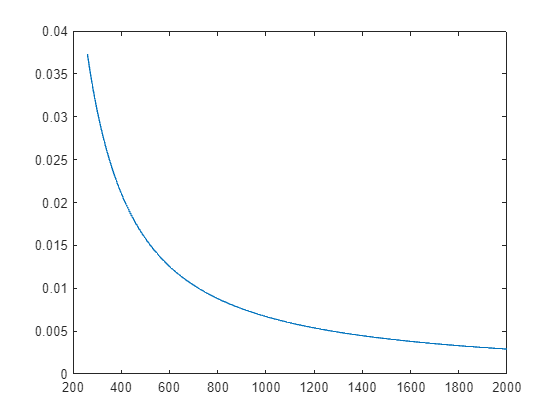

plot(ras, subs(y, ra, ras))

dVt = subs(dVt, {mu, re}, {3.986e5, 6368})

$$dVt = \frac{\sqrt{796}\,\sqrt{49825}\,\left(\sqrt{\frac{\mathrm{ra}-6368}{\mathrm{ra}+6368}+1}-1\right)}{796}-\sqrt{\frac{398600}{\mathrm{ra}}}\,\left(\sqrt{1-\frac{\mathrm{ra}-6368}{\mathrm{ra}+6368}}-1\right)$$

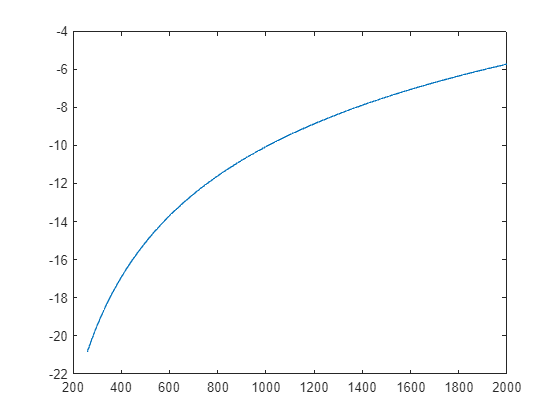

plot(ras, subs(dVt, ra, ras))